% clear;
data = load('resultadosCSV_100khz.txt');

stop    = data(:, 1);
start   = data(:, 2);
coarse  = data(:, 3);

tau_stop    = 15.72e-12;
n_min_stop  = 35;
n_max_stop  = 353;
tau_start   = 16.23e-12;
n_min_start = 27

n_min_start =     27


n_max_start = 335

n_max_start =    335


T           = 5e-9;

T_buscado = 1/(2*100e3)

T_buscado =      5.000000000000000e-06


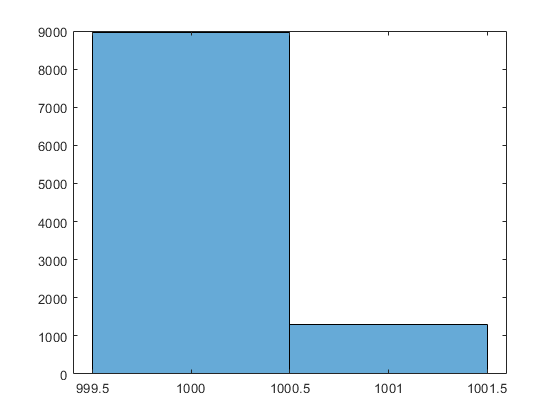

% t_fino = (start)*tau_start - (stop)*tau_stop;
t_fino = (start-stop)*tau_stop;
t = (coarse*T) + t_fino;

histogram(coarse)

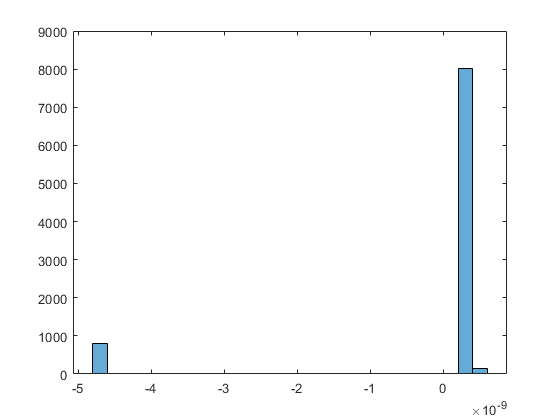

indices_1000 = find(coarse==1000);
indices_1001 = find(coarse==1001);

%%Cuentas 1000
fino_1000 = t_fino(indices_1000);
coarse_1000 = coarse(indices_1000);
cant_1000 = length(indices_1000);
histogram(fino_1000);

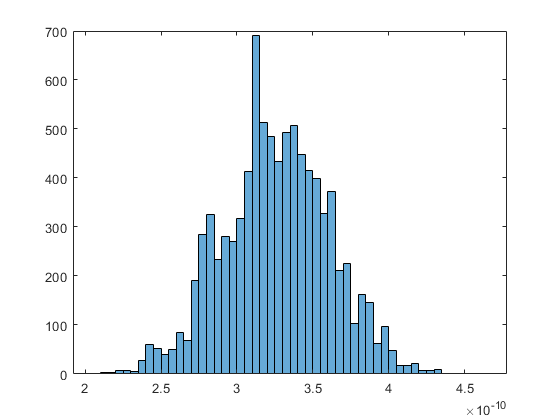

fino_1000_buenos = fino_1000(fino_1000>0);
coarse_1000_buenos = coarse_1000(fino_1000>0);
fino_1000_malos  = fino_1000(fino_1000<0);
coarse_1000_malos = coarse_1000(fino_1000<0);
histogram([fino_1000_buenos; fino_1000_malos+T])

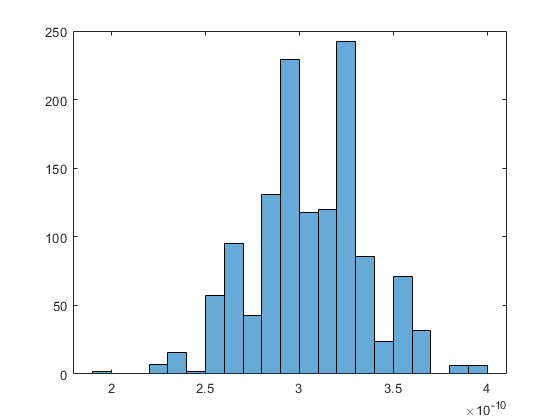


%%Cuentas 1001
%%Se le debe restar una cuenta!!
coarse_1001 = coarse(indices_1001);
fino_1001 = t_fino(indices_1001);
cant_1001 = length(fino_1001);
histogram(fino_1001);

st = start-stop

st =     20
    14
    20
    14
    16
    18
    18
    16
    18
    16


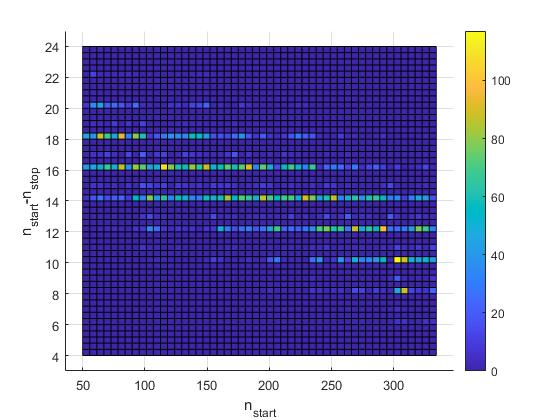

indices_st_pos = find(st>0);
indices_st_neg = find(st<0);
st(indices_st_neg) = st(indices_st_neg) + (n_max_start-n_min_start);
% std(st_positivo)
hist3([start(indices_st_pos), st(indices_st_pos)], 'CdataMode','auto', 'Nbins',[50 50])
view(2); colorbar; ylabel('n_{start}-n_{stop}'); xlabel('n_{start}')
exportgraphics(gcf,'start-stop_100k.eps');

clf;
y = [fino_1000_buenos; fino_1000_malos+T; fino_1001];
presicion = std(y)

presicion =      3.509054591965578e-11


media     = mean(y)

media =      3.236031748046849e-10


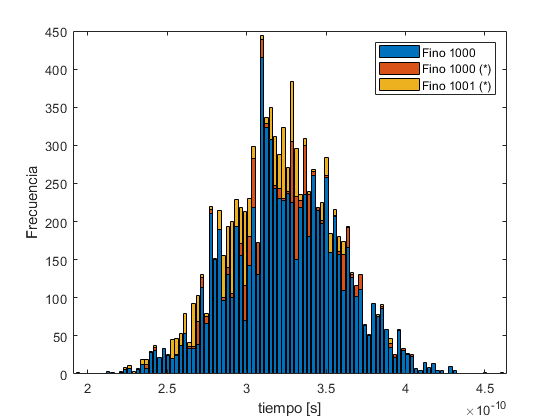

coarse_correcto = 1000;
N = 100;
% Clear figure
clf;

% Data vectors
data = {fino_1000_buenos; fino_1000_malos+T; fino_1001};

% Number of bins
N = 100;

% Determine the range for the common bin edges
all_data = y;
min_val = min(all_data);
max_val = max(all_data);

% Create common bin edges
commonEdges = linspace(min_val, max_val, N+1);

% Preallocate array for counts
countsMatrix = zeros(N, length(data));

% Calculate counts using common edges
for i = 1:length(data)
    countsMatrix(:, i) = histcounts(data{i}, commonEdges);
end
% Create stacked bar plot
bar(commonEdges(1:end-1), countsMatrix, 'stacked');
xlabel('tiempo [s]');
ylabel('Frecuencia');
legend({'Fino 1000', 'Fino 1000 (*)', 'Fino 1001 (*)'});
exportgraphics(gcf,'histograma_100k.eps');


format long
T_buscado

T_buscado =      5.000000000000000e-06


Tiempo_final = 1000*T + media

Tiempo_final =      5.000323603174805e-06


error = Tiempo_final - T_buscado

error =      3.236031748047165e-10


clf;
% Clear figure
clf;

% Data vectors
data = {coarse_1000_buenos, coarse_1000_malos, coarse_1001};

% Number of bins
N = 8;

% Determine the range for the common bin edges
all_data = y;
min_val = min(all_data);
max_val = max(all_data);

% Create common bin edges
commonEdges = 999.5:0.25:1001.5

commonEdges = 	1.0e+03 *

   0.999500000000000   0.999750000000000   1.000000000000000   1.000250000000000   1.000500000000000   1.000750000000000   1.001000000000000   1.001250000000000   1.001500000000000


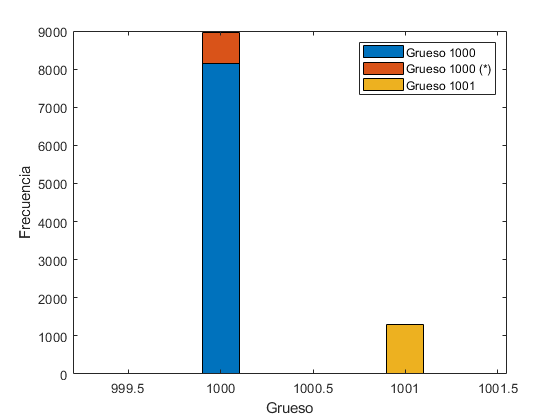


% Preallocate array for counts
countsMatrix = zeros(N, length(data));

% Calculate counts using common edges
for i = 1:length(data)
    countsMatrix(:, i) = histcounts(data{i}, commonEdges);
end

bar(commonEdges(1:end-1), countsMatrix, 'stacked');
xlabel('Grueso');
ylabel('Frecuencia');
legend({['Grueso 1000'], 'Grueso 1000 (*)', 'Grueso 1001'});
exportgraphics(gcf,'histograma_coarse_100k.eps');